# Simulate imaging of a point object embedded in a material

This live script attempts to reproduce figure 4 from Booth et al., Journal of Microscopy, Vol. 192, Pt 2, Nov. 1998 (https://doi.org/10.1111/j.1365-2818.1998.99999.x).

In this simulation we model a small source embeded in a material with a different refractive index to the material surrounding the objective.  The interface between the two materials is a simple plane.  We use otslm.simple.aberrationRiMismatch to simulate the aberration from the refractive index mismatch.  To simulate imaging, we use otslm.tools.spatial_filter with the aberration phase mask and an aperture to simulate a finite collection aperture of the objective.

To generate pattern similar to the last two rows of figure 4 from the paper, we use otslm.simple.zernike to calculate the Zernike polynomial aberration corrections.  To produce high resolution versions you may need to adjust the simulation pattern size.

Parameters describing simulation

addpath('../../');  % Add OTSLM to path
sz = [512, 512];    % Size of the simulation patterns
radius = 31% Radius of objective aperture (pixels)

radius = 31

## Setup aberration mask

depth =100% Depth in material (units of wavelength)

depth = 100

index_objective = 1.5% Refractive index surrounding objective

index_objective = 1.5000

index_material =1.3% Refractive index surrounding particle

index_material = 1.3000

alpha = 0.35% Capture angle (related to focal length and radius)

alpha = 0.3500

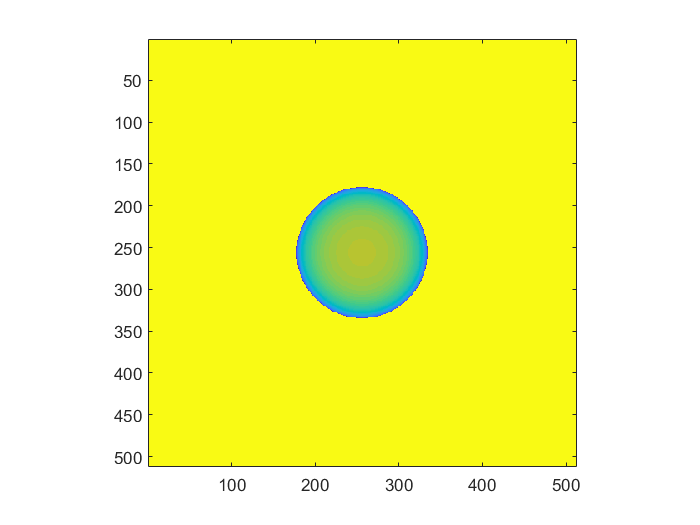


aberration = otslm.simple.aberrationRiMismatch(sz, index_objective, index_material, alpha, ...
    'depth', depth, 'radius', radius);
imagesc(aberration); axis image;
colormap(parula);

## Setup aperture mask

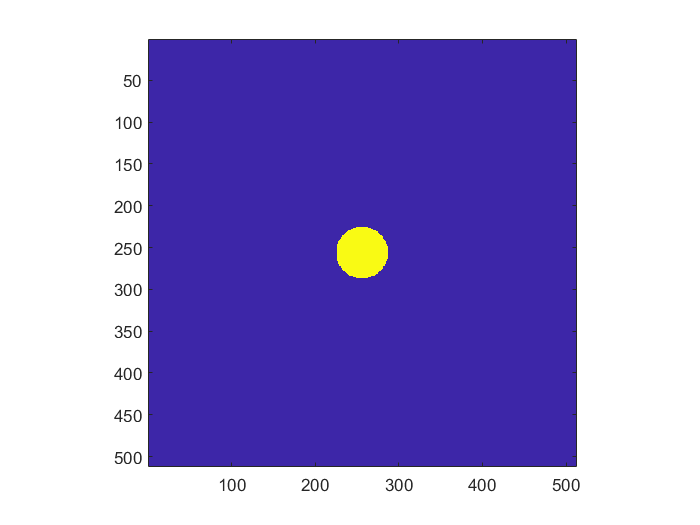

aperture = otslm.simple.aperture(sz, radius, 'shape', 'circle', 'value', [0, 1]);
imagesc(aperture); axis image;

## Add aberration Zernike corrections

This code calculates the overlap between the first few Zernike polynomials and the spherical aberration.  If N is not zero, the first few Zernike terms are subtracted from the aberration.  In an experiment this could be achieved by generating the phase mask for these first few Zernike polynomails using an SLM or deformable mirror.

% Calculate zernike polynomials
Zn2 = otslm.simple.zernike(sz, 0, 2, 'rscale', radius);
Zn4 = otslm.simple.zernike(sz, 0, 4, 'rscale', radius);
Zn6 = otslm.simple.zernike(sz, 0, 6, 'rscale', radius);

% Calculate overlap with aberation
[~, ~, rr] = otslm.simple.grid(sz, 'centre', sz/2);
rr = rr ./ radius;
area = pi ./ sum(aperture(:));
A02 = sum(sum(Zn2 .* aberration)) .* area;
A04 = sum(sum(Zn4 .* aberration)) .* area;
A06 = sum(sum(Zn6 .* aberration)) .* area;

N = 0% Order of aberration corrections (int)

N = 0

if N == 1
    aberration = aberration - A02.*Zn2;
elseif N == 2
    aberration = aberration - A02.*Zn2;
    aberration = aberration - A04.*Zn4;
    aberration = aberration - A06.*Zn6;
elseif N == 0
    % Nothing to do
else
    error('Only 0, 1 and 2 supported');
end
% imagesc(aberration); axis image;

## Combine masks

mask = aperture .* exp(1i*2*pi*aberration);

## Simulate imaging

For the particle we use a small 2 pixel radius aperture.  We then apply the spatial filter and look at the output.

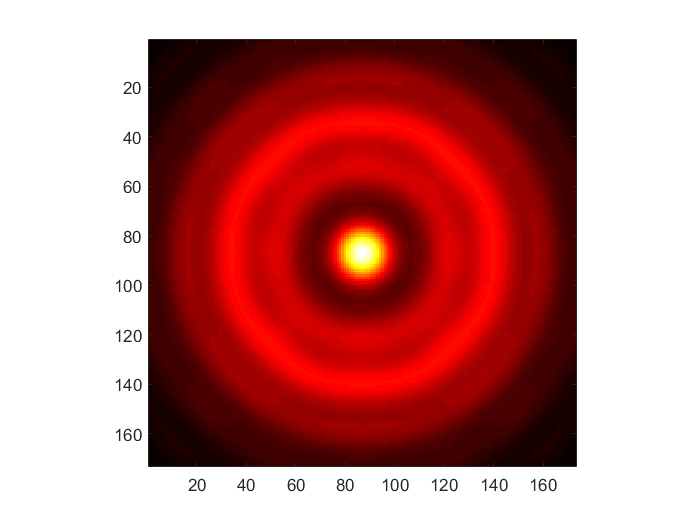

particle_radius = 2;
target = otslm.simple.aperture(sz, particle_radius, 'shape', 'circle', 'value', [0, 1]);
image = otslm.tools.spatial_filter(target, mask);

% Convert image to amplitude-only
image = abs(image).^2;

% Zoom into centre of image
o = 170;
image = image(o:end-o, o:end-o);

imagesc(image); axis image;
colormap(hot);